Detecting lines in images is a very common goal. For instance:

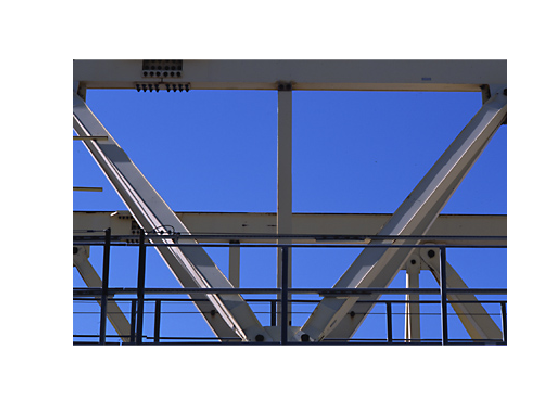

img = imread('gantrycrane.png'); 
imshow(img)

We typically do this with Hough transforms, operating on a binarized, edge-detected grayscale version of the image.

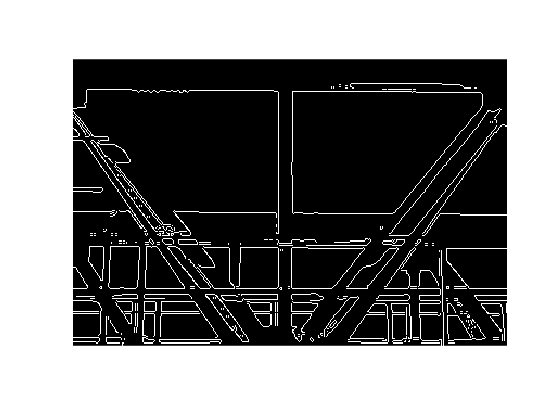

gray = rgb2gray(img);
bw = imbinarize(gray);
bw = edge(bw);
imshow(bw)

Functionality in the Image Processing Toolbox facilitates Hough-based line detections using three functions.

[H,T,R] = hough(bw,'Theta',-90:1:89,'RhoResolution',1);
P = houghpeaks(H,6,'threshold',0.50,'NHoodSize',[7 9]);             
lines = houghlines(bw,T,R,P,'FillGap',20,'MinLength',40);              

We can then visualize the results pretty easily.

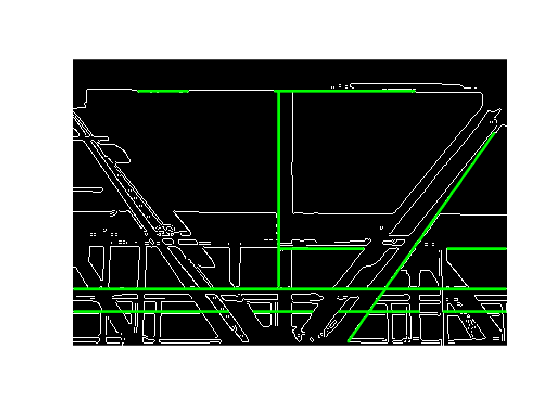

imshow(bw)
hold on
for ii = 1:length(lines)                                            
	xy = [lines(ii).point1; lines(ii).point2];                         
	plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end

Finding the right set of input parameters can be challenging, but the [segmentImage app](https://www.mathworks.com/matlabcentral/fileexchange/48859-segment-images-interactively-and-generate-matlab-code) facilitates the process.

[https://www.mathworks.com/matlabcentral/fileexchange/48859-segment-images-interactively-and-generate-matlab-code](https://www.mathworks.com/matlabcentral/fileexchange/48859-segment-images-interactively-and-generate-matlab-code)

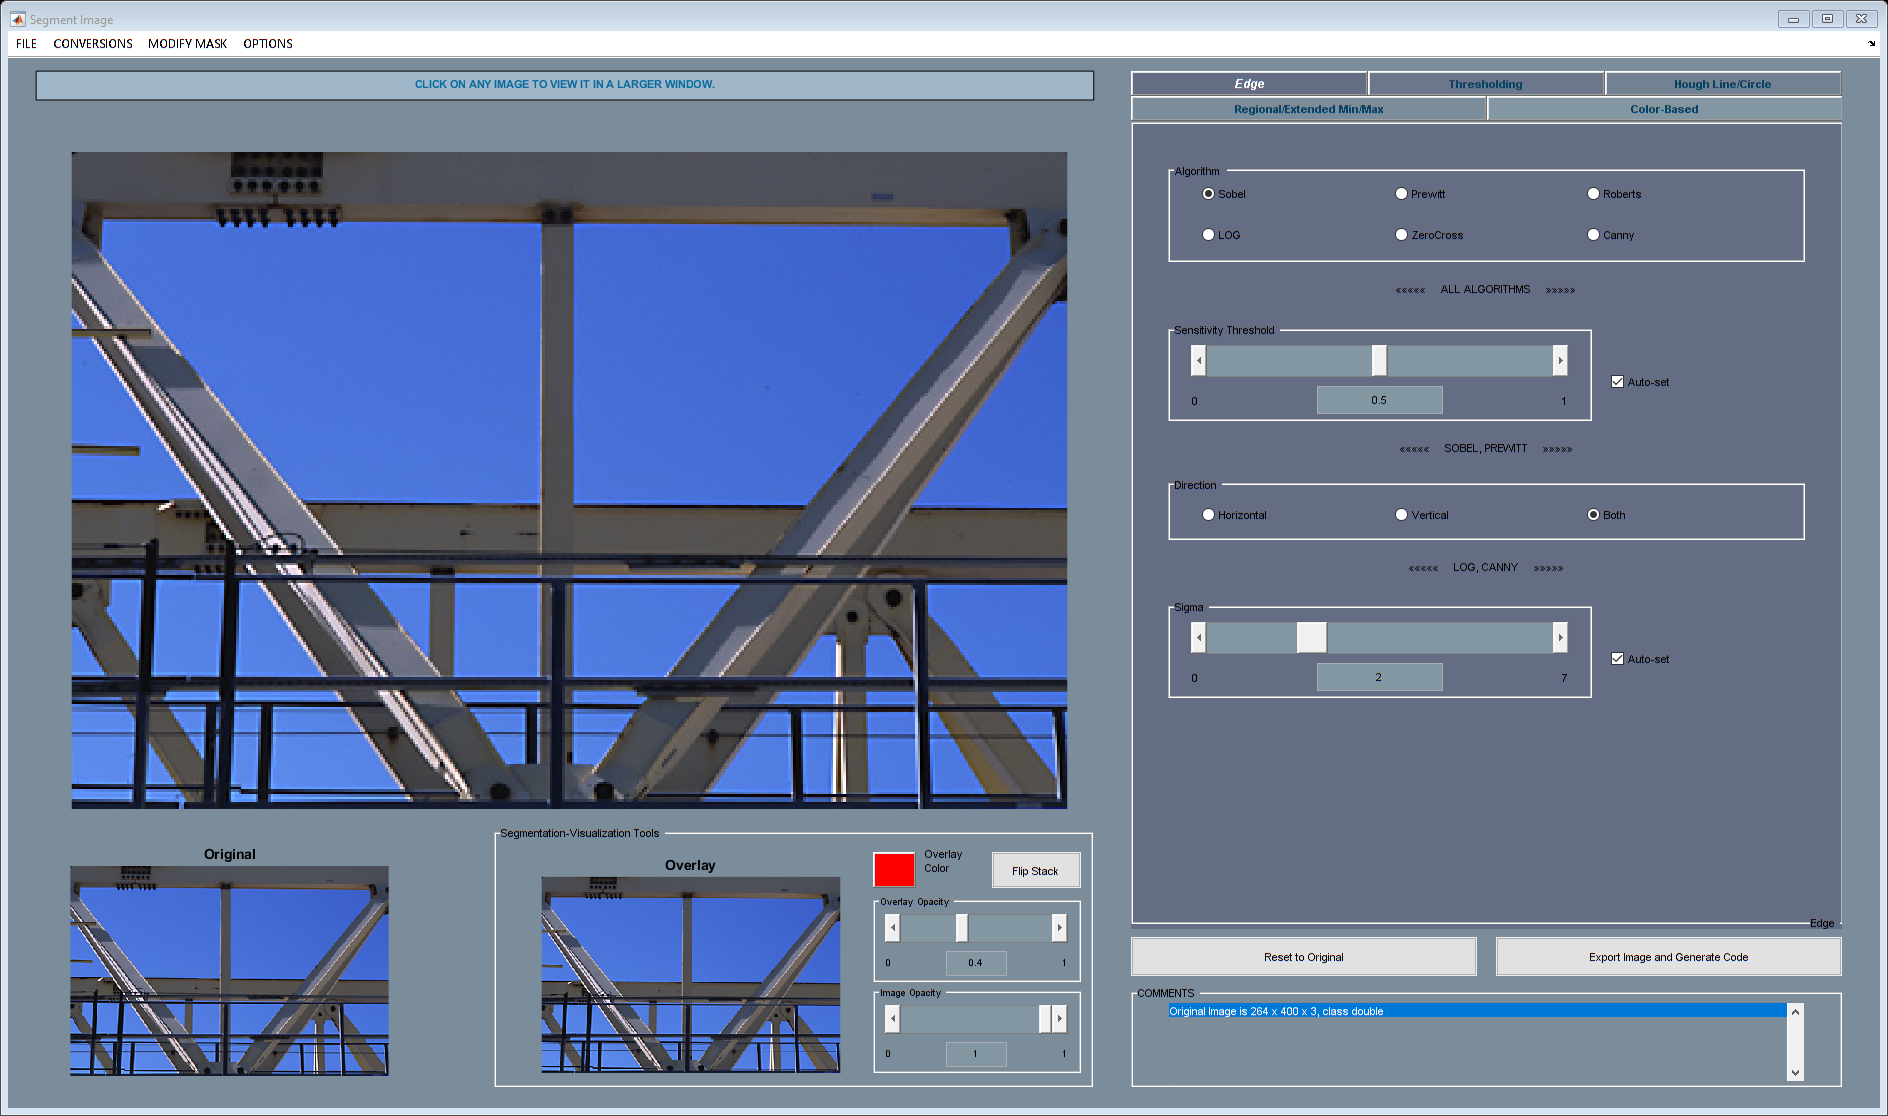

segmentImage(img)

`detectLines` was designed to make this process easier.

detections = detectLines(img, 'numLines', 10)

detections =   detectLines with properties:

              fillGap: 480
              handles: []
       HoughTransform: [957×180 double]
                  img: [264×400×3 uint8]
       lineProperties: []
                lines: [1×10 struct]
            minLength: 40
            NHoodSize: [21 5]
             numLines: 10
             numPeaks: 10
                peaks: [10×2 double]
    preprocessingFcns: {3×1 cell}
         processedImg: [264×400 logical]
                  rho: [1×957 double]
        rhoResolution: 1
                theta: [1×180 double]
             thetaMax: 89
             thetaMin: -90
            thetaStep: 1
            threshold: 0

The companion function `displayResults` makes visualization even easier.

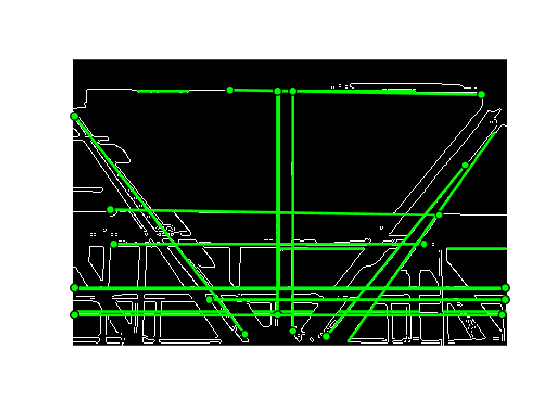

10 Lines displayed.


displayResults(detections)

Sometimes default values don't work. With `detectLines`, you can specify any of the input parameters for hough, houghpeaks, or houghlines.'

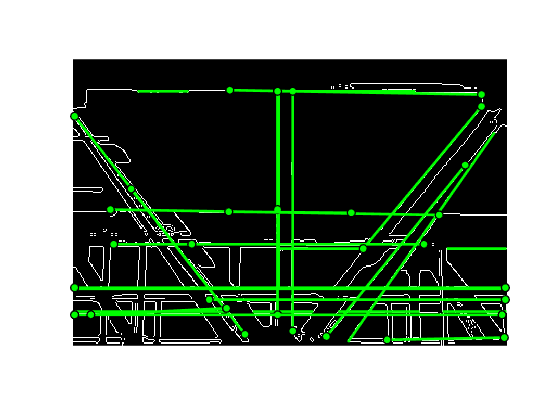

10 Lines displayed.


detections = detectLines(img, ...
     'numPeaks', 10, ... 
     'minLength', 100, ... 
     'NHoodSize', [51 51],... 
     'threshold', 1);
displayResults(detections)

You can also specify any set of custom preprocessing functions to facilitate operating on more challenging images.

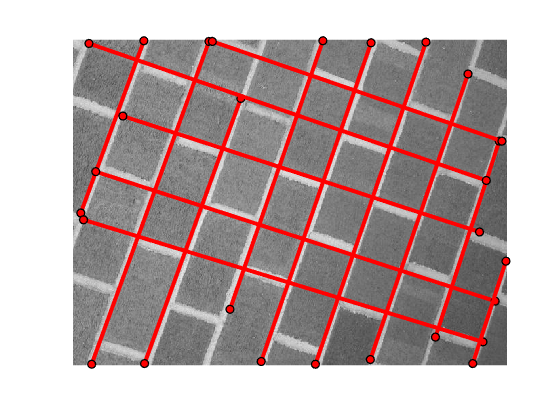

14 Lines displayed.


img = imread('bricksRotated.jpg');
clf;
imshow(img)
detections = detectLines(img, ...
    'preprocessingFcns', ...
    {@imbinarize;
    @(I)edge(I,'LOG');
    @(I)bwareaopen(I, 50)}, ...
    'fillGap', 100, ...
    'threshold', 1, ...
    'numPeaks', 14);
lineOpts.Color = 'r';
lineOpts.LineWidth = 3;
displayResults(detections, lineOpts)

bshoelso@mathworks.com

Copyright 2020 The MathWorks, Inc.